Textfile = load("W3.txt")

Textfile =           20         164         504        8508        -252         208         -36
          20         160         496        8516        -244         225         -58
          20         164         512        8552        -261         235         -36
          20         216         508        8572        -261         235         -36
          20         216         508        8572        -289         255         -48
          20         124         456        8520        -304         290         -63
          20         188         496        8508        -309         269         -34
          20         152         524        8496        -278         314         -57
          20         152         528        8484        -307         327         -74
          20         184         452        8500        -303         314         -39


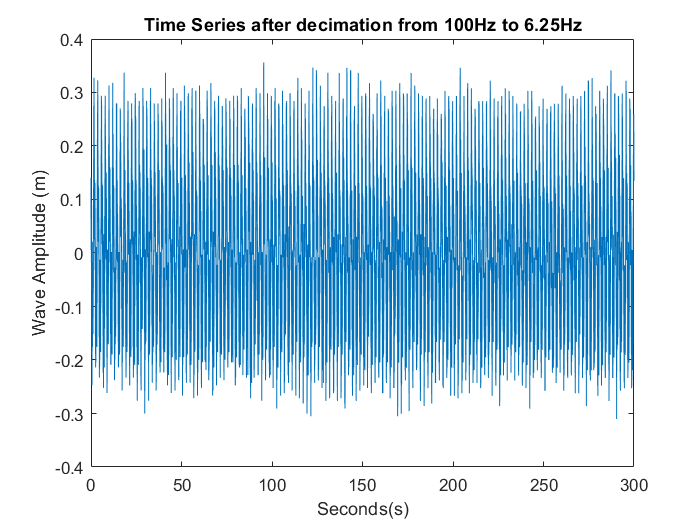

writematrix(Textfile, "W3.csv");
timeSeriesData = readtable("W3.csv");


N =  30000 - 1; 
timeSeriesData = detrend((timeSeriesData{:, 4}/8192*9.81)-9.81); %data is symmetric, *2 to account for contribution of other half 
fs = 100;
time = 1/fs*(0:(N));

plot(time(1:30000), timeSeriesData(1:30000)); %only plotting the real side of the dataset 
title("Time Series after decimation from 100Hz to 6.25Hz");
xlabel("Seconds(s)");
ylabel("Wave Amplitude (m)");